% compare different correlation source

clearvars; close('all');
% GNSS headng
% compass = 'GNSS';
% 
% load("data\CS_GNSS.mat");region='Celtic Sea';
% load("data\RT_GNSS.mat"); region='Rockall Trough';

% sig compasss
compass = 'signature';
load("data\CS_SIG.mat"); region='Celtic Sea';
% load("data\RT_SIG.mat");region='Rockall Trough';

% sig compasss
% compass = 'bottomtrack';
% load("data\IN_BT.mat"); region='Inshore';
% load("data\RT_SIG.mat");region='Rockall Trough';


for mm = 1:numel(WatStruct)

    figure;
    t = tiledlayout(3,1);
    

####     Plot GNSS BEARING AND HEADING


    nexttile
    x=NavStruct(mm).timestamp;
    y=NavStruct(mm).gpsBearing;
    y(y>360)=nan;y(y<0)=nan;
    
    p1=plot(x,y,'b-',...
        'MarkerSize',2);
    hold on
    
    x=NavStruct(mm).timestamp;
    y=NavStruct(mm).gpsHeading;
    y(y>360)=nan;y(y<0)=nan;
    
    p2=plot(x,y,'k-',...
        'MarkerSize',2);
    
    
    x=NavStruct(mm).timestamp;
    y=SensStruct(mm).heading_deg;
    y(y>360)=nan;y(y<0)=nan;
    
    p3=plot(x,y,'m-',...
        'MarkerSize',2);
    
    datetick('x','keeplimits');
    xlabel('Time')
    ylabel('Degrees')
    
    legend('GNSS bearing','GNSS heading','ADCP heading','Location','bestoutside')
    
    

####     Plot current magnitude

    nexttile;
    x=NavStruct(mm).timestamp;
    y=movmean(WatStruct(mm).vMag_ms(1,:),10);
    
    p1=plot(x,y,'k-',...
        'MarkerSize',2);
    datetick('x','keeplimits');
    xlabel('Time')
    ylabel('Bin 1 velocity m s^{-1}')
%     legend('GNSS','ADCP','Location','bestoutside');

####     Plot current DIRECTION

    
    nexttile;
    x=NavStruct(mm).timestamp;
    y=movmean(WatStruct(mm).vDir(1,:),10);
    
    p1=plot(x,y,'k--',...
        'MarkerSize',2);
    
    datetick('x','keeplimits');
    xlabel('Time')
    ylabel('Bin 1 current direction')
%     legend('GNSS','ADCP','Location','bestoutside');
    
    sgtitle([region ' shelf break ' num2str(mm) ' ' datestr(x(1),19) ' to ' datestr(x(1),19)]) ;
    print(gcf,'-dpng',['figures/' region '_correction_check_' num2str(mm)])
    

### Plot currents

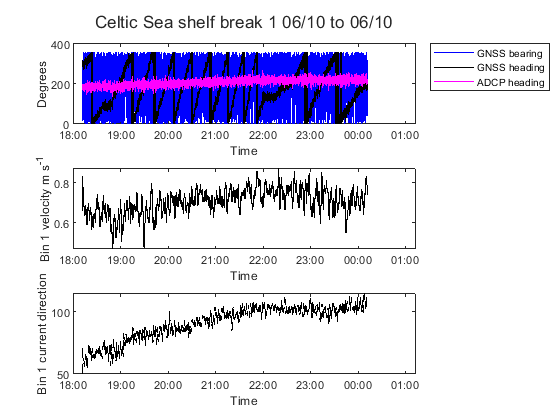

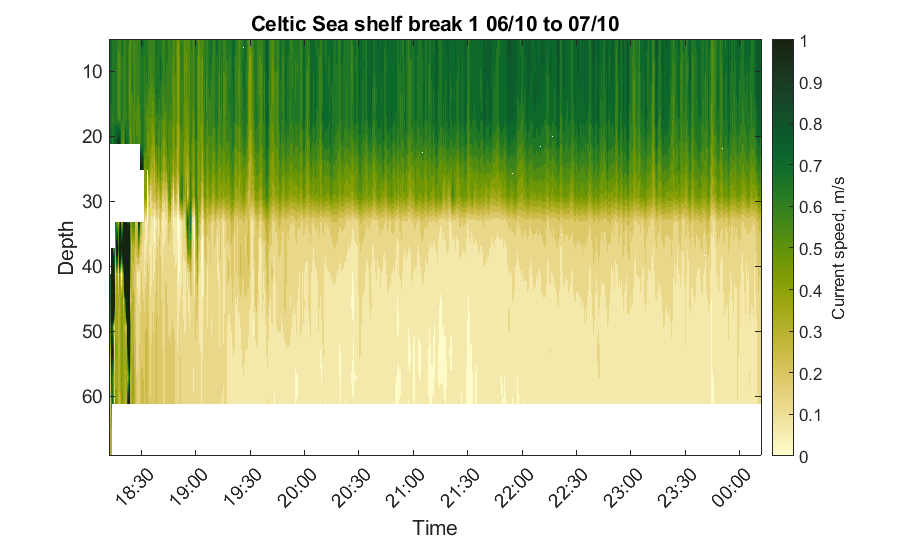

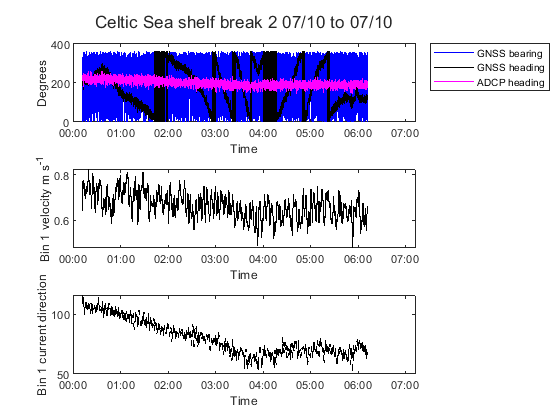

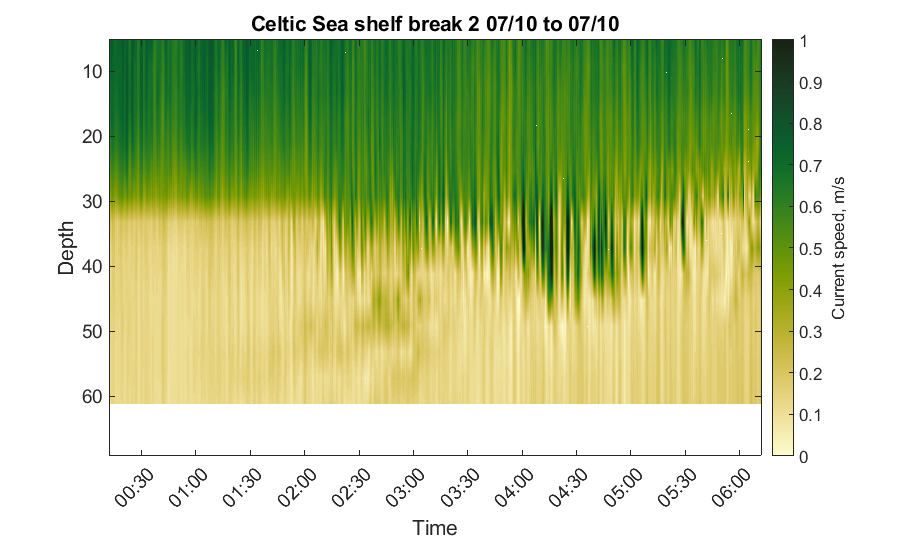

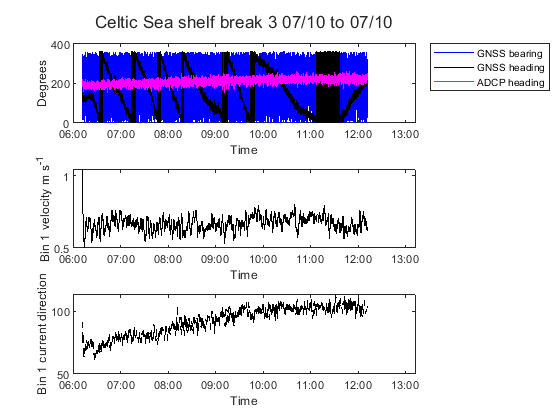

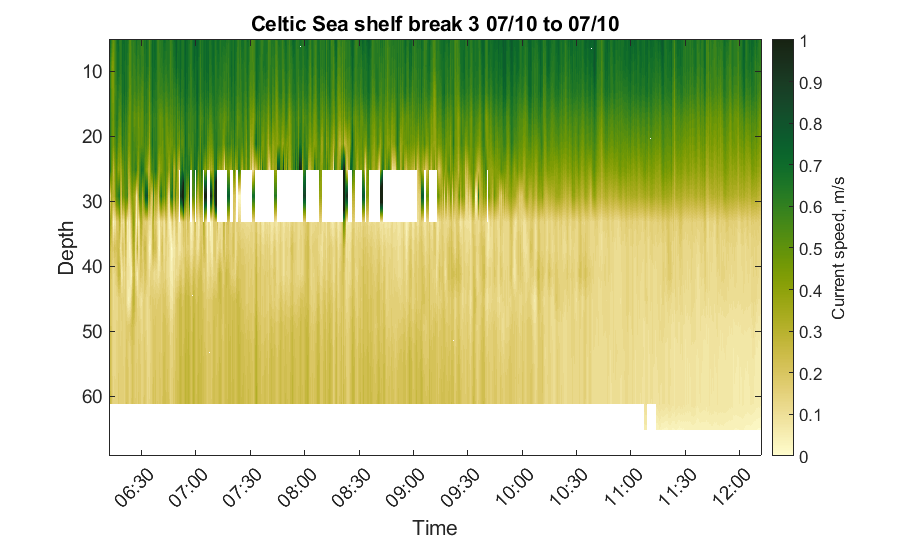

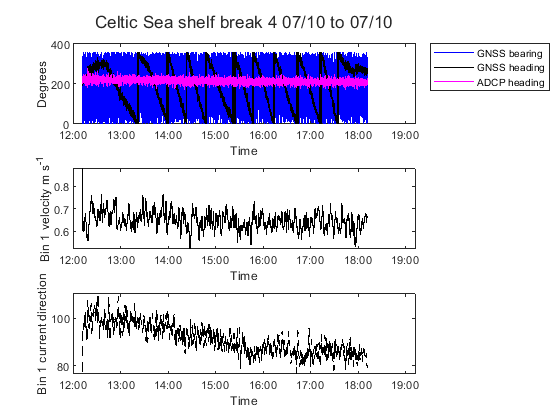

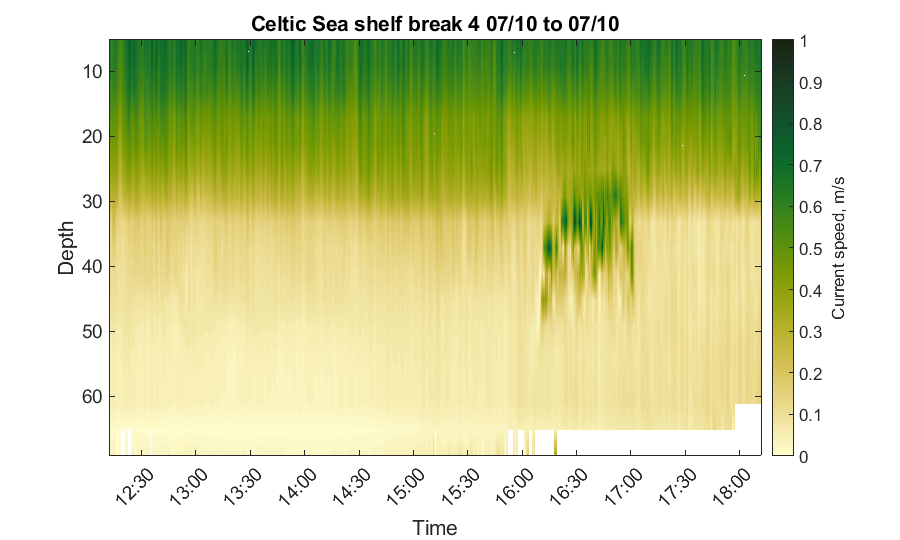

    figure('Renderer', 'painters', 'Position', [10 20 900 540])
    x=NavStruct(mm).timestamp;
    y=WatStruct(mm).binDepth(:,1);
    z=WatStruct(mm).vMag_ms;
    
    contourf(x,y,z,100,'LineColor','none');
     caxis([0 1]);
    cmocean('Speed');
%     cmocean('Balance','pivot',0);
    C=colorbar;
    axis ij
    datetick('x','keeplimits');
    xtickangle(45)
    xlabel('Time');
    ylabel('Depth');
    ylabel(C,'Current speed, m/s');

    title([region ' shelf break ' num2str(mm) ' ' datestr(x(1),19) ' to ' datestr(x(end),19)]) ;
    set(gca,'FontSize',14);
    print(gcf,'-dpng',['figures/' region '_sigvel_' num2str(mm) ' ' compass])
end